## Matlab Tools for HDG in three dimensions

### Exploring and overview of the article

A short overview of the method by *@alujan*

% Let's add to the path the src and drivers: Change as needed
addpath('/Users/chubbs/Documents/UN/HDG/HDG-pilot_example/949_Sayas/Matlab/Drivers/')
addpath('/Users/chubbs/Documents/UN/HDG/HDG-pilot_example/949_Sayas/Matlab/Src/')

#### Running the scripts *HowToUseTheScripts*

At a first glance, what's the  `Parallel Toolbox `?

clear

matlabpool open

'matlabpool' has been removed. With appropriate code changes, use 'parpool' instead.

Caused by:
    Unrecognized function or variable 'matlabpool'.

#### About the Parallel Toolbox

This creates some troubles running the scripts directly, let's explore a little about this module, and what we can expect.

help parpool
% Let's use commands to see how much resources we have to work with
availableGPU = gpuDeviceCount("available") % My case it's 0 because it's gpu integrated
% Let's start a pool on default settings
mypool = parpool()
% How can we control this object? Let's test it's arguments!

% Cluster information
mypool.Cluster
% Attached files to the pool
mypool.listAutoAttachedFiles
% Automatic addition of client path for file finding
mypool.AutoAddClientPath
% Enviroment variables created on the pool
mypool.EnvironmentVariables
% Now let's turn off this thing, but before there's an interesting element
% we can check
gcp('nocreate')         % Current pool
delete(gcp('nocreate')) % End of pool

It's important to note the following graph to select and have clear the aplications and consecuenses of each selection of parallel computing arguments

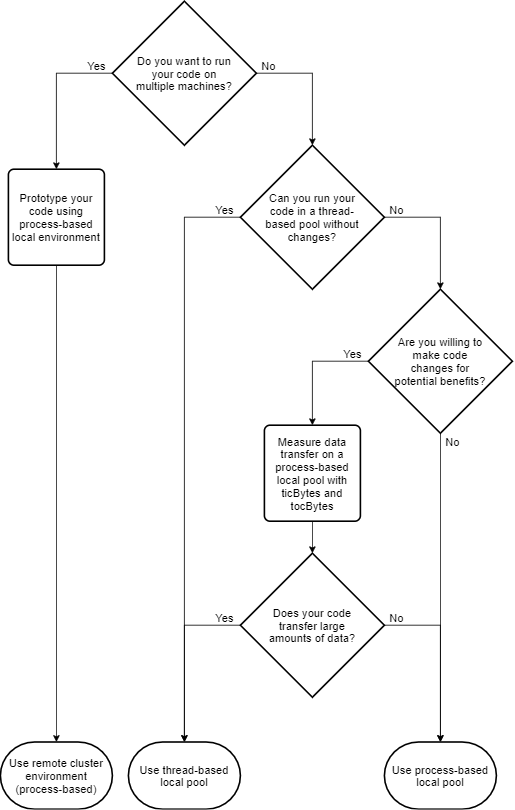

#### Running the scripts

Now that we are a little familiar with the `parallel toolbox` for running the scripts, we can start working

% Run example of the method: Remember to check console for inputs
scriptHDG3dhmethod

We just failed to use the script wanted, but it's ok. Check your enviroment variables, and see that indeed it loaded, but it's having trouble importing, if you ran into this issue, run the load command, and force the method to load locally in  the book

clear   % Clear previous variables
load("Drivers/4Tchimney.mat")

Error using load
Cannot read file /Users/alujan/UN/HDG/949_Sayas/Matlab/Drivers/4Tchimney.mat.

I speculate this is caused because of corruption, then the structure with the maximum refiment can't be accesed. The first runs made of the scripts consists of using the debugging options being able to access and control the steps made during the process. For a more enviroment based run, the algorithm it's going to be break down in sections being able to create a continuous run.

% It's possible to see that for this case the T4 structure it's lost.
matOBJ = matfile('Drivers/4Tchimney.mat')

matOBJ =   matlab.io.MatFile

  Properties:
      Properties.Source: '/Users/chubbs/Documents/UN/HDG/HDG-pilot_example/949_Sayas/Matlab/Drivers/4Tchimney.mat'
    Properties.Writable: false                                                                                    
                 README: [1x93 char]                                                                              
                     T1: [1x1  struct]                                                                            
                     T2: [1x1  struct]                                                                            
                     T3: [1x1  struct]                                                                            

  Methods


#### A Continuous run on the H-Method: Definitions

For this task, we will clear the input need, and the functions are going to be locally ubicated and a local run will be able.

% ------------------------- H-Method Script import ---------------------------- %
% The default input it's going to clear to 1, and the importation of the 
% Dataset wanted it's going to be accesed before the section because of
% corruption. Large loads can't be handled

n=3;
switch n
    case 1
        k=0;
        example=4;
        ctmass=1;
        domain=1;
    case 2
        k=1;
        example=4;
        ctmass=1;
        domain=1;
    case 3
        k=2;
        example=4;
        ctmass=1;
        domain=1;
    case 0
        k=input('Polynomial degree (<=3): ');
        example=input('Input example (1->P1, 2->P2, 3->P3, 4->Cinfty): ');
        ctmass=input('Coefficients: (1) variable; (0) constant: ');
        domain=input('Domain: (1) chimney (2) cube (3) corner: ');
end

The domain selection it's removed, because the files provided a corrupt, in this case, the selection of domain it's going to be changed and the `matfile `method it's going to be used, this handles the problems of loading seen before:

% The domain selection it's manually changed, and it's verified that we can
% access all the lists we have available

switch domain

    % Chimney-shaped domain - Dirichlet = horizontal
    case 1
         matObj = matfile('Drivers/4Tchimney.mat');   % Load of .mat object
         listT  = {matObj.T1, matObj.T2, matObj.T3};  % List of Stuctures available
        %listT = {T} % Example of custom structure.
    
    % (0,1)^3 all Dirichlet
    case 2
        matObj = matfile('Drivers/sixT3dDir.mat');   % Load of .mat object
        listT  = {matObj.T1, matObj.T2, matObj.T3};  % List of Stuctures available
    
    % Fichera corner (uniform partition) - mixex BC
    case 3
        matObj = matfile('Drivers/Corner.mat');   % Load of .mat object
        listT  = {matObj.T1, matObj.T2, matObj.T3};  % List of Stuctures available       
end
% Lastly of convenience the README of each .mat it's displayed
% disp(matObj.README)

The selection of PDE coeffiecients it's mantained, but in this section if you wanted to change the condtions, it's just a matter of changing the value for the variable `ctmass`

% Definition for PDE coefficients kappa and c (Default case it's variable)
% The following definition can be changed if wanted:
ctmass = 1;

switch ctmass

    % Variable coefficients definition, the form it's defined below:
    % the definition must be consistent, definition of kappa and it's
    % gradient.
    case 1
        kappa = @(x,y,z) 2+sin(x).*sin(y).*sin(z);
        kx = @(x,y,z) cos(x).*sin(y).*sin(z);
        ky = @(x,y,z) sin(x).*cos(y).*sin(z);
        kz = @(x,y,z) sin(x).*sin(y).*cos(z);
        c = @(x,y,z) 1.+0.5*(x.^2+y.^2+z.^2);

    % Constant coefficients definition, de form obeys a constant kappa, and
    % the gradient asociated it's zero.
    case 0
        kappa = @(x,y,z) 2+0.*x;
        kx = @(x,y,z) 0.*x;
        ky = @(x,y,z) 0.*x;
        kz = @(x,y,z) 0.*x;
        c = @(x,y,z) 1+0.*x;
end

#### A Continuous run on the H-Method: Quadrature definition

The line `formulas = checkQuadrature3d(k,ctmass); `it's replaced with it's inner definition, only containing the quadrature wanted

% ------------------------- checkQuadrature3d import ---------------------------- %
% Inner checkQuadrature3d subdefinitions
k = k; constantmass = ctmass;

% Importing of the .m scripts containing quadrature information
% - TablesQuadForm3d: The information it's stored in matrices that follows.
%       >> 1st, 4th columns: barycentric coordinates
%       >> 5th columns: weights, sum(weights)=1
%       >> tetraN: formula integrates exactly polynomials of three variables of
%                  degree less than or equal to N
% - TablesQuadForm: The information it's stored in matrices that follows.
%       >> 1st, 3rd columns: barycentric coordinates
%       >> 4th coulmns: weights, sum(weights) = 2

TablesQuadForm3d        % Importing of Reference Tethrahedra
TablesQuadForm          % Importing of matrices

switch constantmass
    case 1
        switch k
            case 0
                formulas={tetra5,tetra1,matrix0,matrix4};
            case 1
                formulas={tetra3,tetra3,matrix4,matrix4};
            case 2
                formulas={tetra7,tetra7,matrix9,matrix9};
            case 3
                formulas={tetra9,tetra9,matrix11,matrix11};
        end
    case 0
        switch k
            case 0 
                formulas={tetra5,tetra1,matrix0,matrix4};
            case 1
                formulas={tetra5,tetra3,matrix4,matrix4};
            case 2
                formulas={tetra7,tetra7,matrix9,matrix9};
            case 3
                formulas={tetra9,tetra9,matrix11,matrix11};
        end
end

% Reduction of weights: Sum of weights it's defined to be equal to 2, for
% normalization it's reduced to 1.
formulas{3}(:,4)=formulas{3}(:,4)/2;
formulas{4}(:,4)=formulas{4}(:,4)/2;

% Reduction of inner variables definitions
clear constantmass
% --------------------------- checkQuadrature3d end ------------------------------ %

% Example definition of exact solution
switch example
    case 1
        u = @(x,y,z) 2*x+3*y+z;
        ux = @(x,y,z) 2+0.*x;
        uy = @(x,y,z) 3+0.*x;
        uz = @(x,y,z) 1+0.*x;
        uxx = @(x,y,z) 0.*x;
        uyy = @(x,y,z) 0.*x;
        uzz = @(x,y,z) 0.*x;
    case 2
        u = @(x,y,z) x.^2+y.*x+z.*y+2*z.^2;
        ux = @(x,y,z) 2*x + y;
        uy = @(x,y,z) x + z;
        uz = @(x,y,z) y + 4*z;
        uxx = @(x,y,z) 2+0.*x;
        uyy = @(x,y,z) 0.*x;
        uzz = @(x,y,z) 4+0.*x;
    case 3
        u = @(x,y,z) 2*x.^2.*y+4*y.^2.*z+3*x.*z.^2;
        ux = @(x,y,z) 3*z.^2 + 4*x.*y;
        uy = @(x,y,z) 2*x.^2 + 8*y.*z;
        uz = @(x,y,z) 4*y.^2 + 6*x.*z;
        uxx = @(x,y,z) 4*y;
        uyy = @(x,y,z) 8*z;
        uzz = @(x,y,z) 6*x;
    case 4
        u = @(x,y,z) sin(x.*y.*z);
        ux = @(x,y,z) y.*z.*cos(x.*y.*z);
        uy = @(x,y,z) x.*z.*cos(x.*y.*z);
        uz = @(x,y,z) x.*y.*cos(x.*y.*z);
        uxx = @(x,y,z) -y.^2.*z.^2.*sin(x.*y.*z);
        uyy = @(x,y,z) -x.^2.*z.^2.*sin(x.*y.*z);
        uzz = @(x,y,z) -x.^2.*y.^2.*sin(x.*y.*z);
end

% Conditions definition: PDE
uD = u;                                     % Dirichlet condition
km = @(x,y,z) 1./kappa(x,y,z);              % Inverse kappa calculation
qx = @(x,y,z) -kappa(x,y,z).*ux(x,y,z);     % Calculation of vector components
qy = @(x,y,z) -kappa(x,y,z).*uy(x,y,z);     % of inv(kappa) .* q
qz = @(x,y,z) -kappa(x,y,z).*uz(x,y,z);     %

% Construction of f element: In example we know u
f = @(x,y,z) -(kx(x,y,z).*ux(x,y,z)+kappa(x,y,z).*uxx(x,y,z))...
             -(ky(x,y,z).*uy(x,y,z)+kappa(x,y,z).*uyy(x,y,z))...
             -(kz(x,y,z).*uz(x,y,z)+kappa(x,y,z).*uzz(x,y,z))...
             +c(x,y,z).*u(x,y,z);

% Construction of g element: In example we know u
gx = @(x,y,z) -qx(x,y,z);         
gy = @(x,y,z) -qy(x,y,z);  
gz = @(x,y,z) -qz(x,y,z); 

a = @(x,y,z) 0.*x;      

% Error elements definition for display handle
ErrorU=[];
ErrorQ=[];
ErrorUhat=[];
ErrorPu=[];
ErrorPuhat=[];
ErrorUstar=[];
h=[];

% Norms of unknowns for relative error
Tmax=listT{end};                    % Listing of T elements
Nelts=size(Tmax.elements,1);        % Number of elements enlisted
d3=nchoosek(k+3,3);                 % d_i definition of set (cardinality)

#### A Continuous run on the H-Method:  Norm of solutions for error definitions

The `errorElem `function it's used for this task, the idea used it's comparison with the origin that leaves the norm of elements $\mathit{\mathbf{u}}$and $\mathit{\mathbf{q}}$with known solution


$$|\mathit{\mathbf{p}}-{\mathit{\mathbf{p}}}^* |_{L^2 } \;=|\mathit{\mathbf{p}}|_{L^2 } \;:{\mathit{\mathbf{p}}}^* =0$$


% Computation of norm for U & Q
% The second element it's considered to be null, this leaves the
% calculation of error: error: \| p - ph \|_{L^2} to be just the
% calculation of \| p \|_{L^2} which it's the norm. It's abused the fact
% that the integral calculation it's made on the Dubiner basis.

normU=errorElem(Tmax,u,zeros(d3,Nelts),k,formulas{1});

normQ=errorElem(Tmax,qx,zeros(d3,Nelts),k,formulas{1})...
        +errorElem(Tmax,qy,zeros(d3,Nelts),k,formulas{1})...
        +errorElem(Tmax,qz,zeros(d3,Nelts),k,formulas{1});

#### A Continuous run on the H-Method:  The main iteration

Here the main iteration can't be break down in all the inner references into sections, then the following sequence is going to be long, although the inner functions are going to be expanded and explained.

% Sequence definition for each structure inside the list of Tetrahedron
% definitions.
for i=1:length(listT)

    % Particular partition definitions
    T=listT{i};                 % i-th Partition of space
    Nelts=size(T.elements,1);   % Number of elements inside the partition

    % ------------------------ create tau 3D -------------------------- %
    % The function creates for option a matrix with the coeficients of 
    % the polynomial tau.

    % Inner definitions:
    Nelts = Nelts; option = 1;

    switch option

    % (1) tau = 1
    case 1
        tau=ones(4,Nelts);

    % (2) SFHDG on the first face
    case 2
        tau=[ones(1,Nelts);...
             zeros(3,Nelts)];

    % (3) SFHDG on a random face
    case 3
        where=ceil(4*rand(1,Nelts));
        tau=sparse(where,1:Nelts,1);
        tau=full(tau);
    end

    % Reduction of inner variables definitions
    clear option
    % ----------------------- end create tau 3D ---------------------- %

    % Example of run %
    % curl=curlMatrix(T,k,formulas{1});

    % HDG3D main function: Reviewed in the imported functions section
    [Uh,Qxh,Qyh,Qzh,Uhat]=HDG3d(km,c,f,tau,T,k,formulas,uD,gx,gy,gz);

    normUhat=errorFaces(T,u,zeros(size(Uhat)),k,formulas{4});
    
    % Errors with exact solution
    error_uhat= errorFaces(T,u,Uhat,k,formulas{4});
    error_q   = errorElem(T,qx,Qxh,k,formulas{1})...
               +errorElem(T,qy,Qyh,k,formulas{1})...
               +errorElem(T,qz,Qzh,k,formulas{1});
    error_u   = errorElem(T,u,Uh,k,formulas{1});

    ErrorQ=[ErrorQ error_q/normQ]; 
    ErrorU=[ErrorU error_u/normU];
    ErrorUhat=[ErrorUhat error_uhat/normUhat];
    
    % Errors with projections
    Puhat=L2projskeleton3d(u,T,k,formulas{3},formulas{4});

    [Pqx,Pqy,Pqz,Pu]=projectHDG3d(T,{qx,qy,qz,u},k,tau,formulas);
    error_Puhat=errorFaces(T,a,Uhat-Puhat,k,formulas{4});
    error_Pu=errorElem(T,a,Pu-Uh,k,formulas{1});

    ErrorPu=[ErrorPu error_Pu/normU];
    ErrorPuhat=[ErrorPuhat error_Puhat/normUhat];
    
    % Postprocessing
    Uhstar=postprocessing(T,km,Qxh,Qyh,Qzh,Uh,k,formulas{1});
    
    error_Ustar=errorElem(T,u,Uhstar,k+1,formulas{1});
    ErrorUstar=[ErrorUstar error_Ustar/normU];
       
    h=[h 1/(2^i)];
end

#### A Continuous run on the H-Method:  Convergence

The following sequence computes the order of convergence using the formula:


$$\frac{\log_2 \left(e_{h/2} \right)}{\log_2 \left(e_h \right)}$$


And the relative errores are computed as function of $k$ whenever the rates:


$$\frac{\log_2 \left(e_k /e_{k+1} \right)}{\log_2 \left(e_{k+1} /e_{k+2} \right)}\approx 1$$


% Rate of sucesion: Convergence verification
rateQ=log2(ErrorQ(1:end-1)./ErrorQ(2:end));
rateU=log2(ErrorU(1:end-1)./ErrorU(2:end));
rateUhat=log2(ErrorUhat(1:end-1)./ErrorUhat(2:end));
ratePu=log2(ErrorPu(1:end-1)./ErrorPu(2:end));
ratePuhat=log2(ErrorPuhat(1:end-1)./ErrorPuhat(2:end));
rateUstar=log2(ErrorUstar(1:end-1)./ErrorUstar(2:end));

#### A Continuous run on the H-Method:  Display of results

The following sequence just displays in somewhat a tabular structure the results and comparing with the solutions.

% Display sequence of values
format bank
disp('Rate |Q-Qh|   Rate |U-Uh|     Rate |U-Uhat|_h');

Rate |Q-Qh|   Rate |U-Uh|     Rate |U-Uhat|_h


disp([rateQ' rateU' rateUhat']);

         -0.04          0.00         -0.00
         -0.01          0.00         -0.00
          0.05         -0.00          0.00
         -0.04          0.00         -0.00
         -0.01          0.00         -0.00



disp('Rate |\Pi u-Uh|  Rate |Pu-Uhat|_h  Rate |U-U*|')

Rate |\Pi u-Uh|  Rate |Pu-Uhat|_h  Rate |U-U*|


disp([ratePu' ratePuhat' rateUstar']);

          0.00         -0.00         -0.07
          0.00         -0.00         -0.02
         -0.00          0.00          0.09
          0.00         -0.00         -0.07
          0.00         -0.00         -0.02



format shortE
disp('Error |Q-Qh|   Error |U-Uh|     Error |U-Uhat|_h');

Error |Q-Qh|   Error |U-Uh|     Error |U-Uhat|_h


disp([ErrorQ' ErrorU' ErrorUhat']);

   2.3531e-01   1.0179e+00   1.0156e+00
   2.4146e-01   1.0155e+00   1.0170e+00
   2.4329e-01   1.0145e+00   1.0179e+00
   2.3531e-01   1.0179e+00   1.0156e+00
   2.4146e-01   1.0155e+00   1.0170e+00
   2.4329e-01   1.0145e+00   1.0179e+00



disp('Error |\Pi u-Uh|  Error |Pu-Uhat|_h Error |U-U*|')

Error |\Pi u-Uh|  Error |Pu-Uhat|_h Error |U-U*|


disp([ErrorPu' ErrorPuhat' ErrorUstar']);

   1.0165e+00   1.0154e+00   9.5165e-01
   1.0154e+00   1.0170e+00   9.9631e-01
   1.0145e+00   1.0179e+00   1.0094e+00
   1.0165e+00   1.0154e+00   9.5165e-01
   1.0154e+00   1.0170e+00   9.9631e-01
   1.0145e+00   1.0179e+00   1.0094e+00



#### Processing of a GMSH Structure 

Right now we got the function `run.m` where we're able to create the basics of a structure, but, How do we implement the rest of the structure Sayas used?

% Example of use, we have in path an example, the cubeD.geo, here we're
% going to compare the values on the structure with Sayas Chimney4T
run

Firstly, we're going to explore the designation of values and organization of structure

% Organizaremos como Sayas, la estructura en un valor T
T.coordinates = Coordinates;

Unrecognized function or variable 'Coordinates'.

T.elements    = Elements;

% Processing to get the dirichlet and Neuman surfaces
% - Dirichlet : identifier (50)
dirichlet_mask = malla.TRIANGLES(:, 4) == 50;
dirichlet_surfaces = malla.TRIANGLES(dirichlet_mask, 1:3);

% - Neumann : identifier (60)
neumann_mask = malla.TRIANGLES(:, 4) == 60;
neumann_surfaces = malla.TRIANGLES(neumann_mask, 1:3);

% Addition to structure
T.dirichlet = dirichlet_surfaces;
T.neumann   = neumann_surfaces;

% Construction of a list of all faces
shape=[1 3 2;1 2 4;1 4 3;2 3 4];
nelts=size(T.elements,1);
faces=zeros(4*nelts,3);
 for k=1:nelts
     nodes=T.elements(k,:); %1x4
     faces(4*(k-1)+(1:4),:)=nodes(shape); % 1x3
 end

% Processing of faces
copyoffaces=faces;  % 4 nelts x 3 (in local positive orientation)
faces=sort(faces,2);

% Storage of unique values for faces (No repetition)
[allfaces,~,j]=unique(faces,'rows');

% Difference and Intersection of Boundary Faces
bdfaces=sort([T.dirichlet;T.neumann],2);
[intfaces,i]=setdiff(allfaces,bdfaces,'rows');
[bdfaces,ii,jj]=intersect(allfaces,bdfaces,'rows');

nintfaces=size(intfaces,1);
ndirfaces=size(T.dirichlet,1);
nneufaces=size(T.neumann,1);
nbdfaces =size(bdfaces,1);
nfaces   =nintfaces+nbdfaces;

% Interior Faces ∩ Neumann Faces ∩ Dirichlet Faces = Total Faces
T.faces=[intfaces zeros(nintfaces,1);...
         T.dirichlet ones(ndirfaces,1);...
         T.neumann 2*ones(nneufaces,1)];
T.dirfaces=(nintfaces+1):(nintfaces+ndirfaces);
T.neufaces=(nintfaces+ndirfaces+1):(nintfaces+ndirfaces+nneufaces);

% Backward referencing to construct T.facebyele
u=zeros(nfaces,1);
v=nintfaces+1:nintfaces+nbdfaces;
u(i)=1:nintfaces;
u(ii)=v(jj);
j=u(j);                % pointer from T.faces to the copyoffaces
faces=T.faces(j,1:3);  % 4 nelts x 3, with global numbering of nodes
j=reshape(j,[4 nelts]);
T.facebyele=j';

% Matrix with orientations
A=T.facebyele';
faces=T.faces(A(:),1:3);
t=sum(faces==copyoffaces,2)==ones(4*nelts,1);
t=1-2*t;t=reshape(t,[4,nelts]);
T.orientation=t';

% Matrix with permutation order
eq = @(u,v) sum(u==v,2)==3; % checks what rows are equal
rot=[1 2 3;...              % permutations 
     1 3 2;...
     3 1 2;...
     3 2 1;...
     2 3 1;...
     2 1 3];
pattern=[1 2 3;...    % (s,t,0)
         1 2 4;...    % (s,0,t)
         1 3 4;...    % (0,s,t)
         4 2 3];      % (s,t,1-s-t)
orient=zeros(nelts,4);

for f=1:4    % counter over faces
    faceGlobal=T.faces(T.facebyele(:,f),1:3);
    faceLocal =T.elements(:,pattern(f,:));
    for j=1:6
        orient(:,f)=orient(:,f)+j*eq(faceGlobal,faceLocal(:,rot(j,:)));
    end
end
T.perm=orient;

% Volumes 
T.volume=(1/6)*...
 ((T.coordinates(T.elements(:,2),1)-T.coordinates(T.elements(:,1),1)).*...
     (T.coordinates(T.elements(:,3),2)-T.coordinates(T.elements(:,1),2)).*...
     (T.coordinates(T.elements(:,4),3)-T.coordinates(T.elements(:,1),3))-...
  (T.coordinates(T.elements(:,2),1)-T.coordinates(T.elements(:,1),1)).*...
     (T.coordinates(T.elements(:,3),3)-T.coordinates(T.elements(:,1),3)).*...
     (T.coordinates(T.elements(:,4),2)-T.coordinates(T.elements(:,1),2))-...
  (T.coordinates(T.elements(:,2),2)-T.coordinates(T.elements(:,1),2)).*...
     (T.coordinates(T.elements(:,3),1)-T.coordinates(T.elements(:,1),1)).*...
     (T.coordinates(T.elements(:,4),3)-T.coordinates(T.elements(:,1),3))+...
  (T.coordinates(T.elements(:,2),2)-T.coordinates(T.elements(:,1),2)).*...
     (T.coordinates(T.elements(:,3),3)-T.coordinates(T.elements(:,1),3)).*...
     (T.coordinates(T.elements(:,4),1)-T.coordinates(T.elements(:,1),1))+...
  (T.coordinates(T.elements(:,2),3)-T.coordinates(T.elements(:,1),3)).*...
     (T.coordinates(T.elements(:,3),1)-T.coordinates(T.elements(:,1),1)).*...
     (T.coordinates(T.elements(:,4),2)-T.coordinates(T.elements(:,1),2))-...
  (T.coordinates(T.elements(:,2),3)-T.coordinates(T.elements(:,1),3)).*...
     (T.coordinates(T.elements(:,3),2)-T.coordinates(T.elements(:,1),2)).*...
     (T.coordinates(T.elements(:,4),1)-T.coordinates(T.elements(:,1),1)));

% Areas definition
x_coordinate = ((T.coordinates(T.faces(:,2),2)-T.coordinates(T.faces(:,1),2)).*...
  (T.coordinates(T.faces(:,3),3)-T.coordinates(T.faces(:,1),3))-...
  (T.coordinates(T.faces(:,2),3)-T.coordinates(T.faces(:,1),3)).*...
  (T.coordinates(T.faces(:,3),2)-T.coordinates(T.faces(:,1),2))).^2;

y_coordinate = ((T.coordinates(T.faces(:,2),1)-T.coordinates(T.faces(:,1),1)).*...
  (T.coordinates(T.faces(:,3),3)-T.coordinates(T.faces(:,1),3))-...
  (T.coordinates(T.faces(:,2),3)-T.coordinates(T.faces(:,1),3)).*...
  (T.coordinates(T.faces(:,3),1)-T.coordinates(T.faces(:,1),1))).^2;

z_coordinate = ((T.coordinates(T.faces(:,2),1)-T.coordinates(T.faces(:,1),1)).*...
  (T.coordinates(T.faces(:,3),2)-T.coordinates(T.faces(:,1),2))-...
  (T.coordinates(T.faces(:,2),2)-T.coordinates(T.faces(:,1),2)).*...
  (T.coordinates(T.faces(:,3),1)-T.coordinates(T.faces(:,1),1))).^2;

T.area=(1/2)*sqrt( x_coordinate + y_coordinate + z_coordinate );
 

% Normals to the faces 
for f=1:4
    oneface=T.faces(T.facebyele(:,f),1:3);
    x=T.coordinates(oneface(:),1);
    y=T.coordinates(oneface(:),2);
    z=T.coordinates(oneface(:),3);
%
    x12=x(nelts+1:2*nelts)-x(1:nelts); %x_2-x_1
    x13=x(2*nelts+1:end)-x(1:nelts);   %x_3-x_1
    y12=y(nelts+1:2*nelts)-y(1:nelts); %y_2-y_1
    y13=y(2*nelts+1:end)-y(1:nelts);   %y_3-y_1
    z12=z(nelts+1:2*nelts)-z(1:nelts); %z_2-z_1
    z13=z(2*nelts+1:end)-z(1:nelts);   %z_3-z_1
 %   
    normals=(1/2)*[y12.*z13-y13.*z12,...
                   z12.*x13-z13.*x12,...
                   x12.*y13-x13.*y12];
    normals=bsxfun(@times,normals,T.orientation(:,f)); % Give the normals correctly orientated
%
    T.normals(:,(f-1)*3+(1:3))=normals;
end

format short
[M1,Cf,A1,A2,Af]=localsolvers3d(km,c,f,tau,T,k,formulas);

F1 = reshape(pagenorm(A2(:, d2+1:2*d2, :)), [1, Nelts])

F1 =     0.0553    0.0782    0.0552    0.0553    0.0552    0.0956    0.0553    0.0782    0.0552    0.0553    0.0552    0.0956    0.0556    0.0747    0.0527    0.0554    0.0525    0.0865    0.0443    0.0626    0.0442    0.0443    0.0442    0.0718    0.0553    0.0782    0.0552    0.0553    0.0552    0.0956    0.0553    0.0782    0.0552    0.0553    0.0552    0.0956    0.0556    0.0744    0.0527    0.0554    0.0525    0.0893    0.0443    0.0626    0.0442    0.0443    0.0442    0.0718    0.0553    0.0781


#### Function import for local verification

It's imported the main function to verify the actions made

function [Uh,Qxh,Qyh,Qzh,Uhat,system,solvers]=HDG3d(km,c,f,tau,T,k,formulas,uD,gx,gy,gz,varargin)
% -------------------------------- HDG 3D main function --------------------------------------- %

%[Uh,Qxh,Qyh,Qzh,Uhat]=HDG3d(km,c,f,tau,T,k,formulas,uD,gx,gy,gz)
%[Uh,Qxh,Qyh,Qzh,Uhat]=HDG3d(km,c,f,tau,T,k,formulas,uD,gx,gy,gz,0)
%[~,~,~,~,~,system,solvers]=HDG3d(km,c,f,tau,T,k,formulas,uD,gx,gy,gz,1)
%
%Input:
%        km   : vectorized function (kappa^{-1}; kappa=diffusion parameter)
%        c    : vectorized function (reaction parameter)
%        f    : vectorized function (source term)
%        tau  : penalization parameter for HDG (Nelts x 4)
%        T    : expanded tetrahedrization
%        k    : polynomial degree
%     formulas: {for1,for2,for3} 
%               (quadrature formulas as used by localsolvers3d)
%        uD   : Dirichlet data; vectorized function
%    gx,gy,gz : Neumann data (corresponds to kappa*grad(u)); vectorized fns  
%
%Output:
%      Uh     : d3 x Nelts,   matrix with uh
%      Qxh    : d3 x Nelts,   matrix with qxh
%      Qyh    : d3 x Nelts,   matrix with qyh
%      Qzh    : d3 x Nelts,   matrix with qzh
%      Uhat   : d2 x Nelts    matrix with uhhat
%    system   : {HDGmatrix,HDGrhs,list of free d.o.f.,list of dir d.o.f.}
%    solvers  : {A1,A2,Af}    local solvers
%
%Last modified: April 11, 2013

if nargin==12
    export=varargin{1};
else
    export=0;
end

d2=nchoosek(k+2,2);    
d3=nchoosek(k+3,3); 
block3=@(x) (1+(x-1)*d3):(x*d3);
Nelts  =size(T.elements,1);
Nfaces =size(T.faces,1);
Ndir   =size(T.dirichlet,1);
Nneu   =size(T.neumann,1);

%Matrices for assembly process

face=T.facebyele';                  % 4 x Nelts
face=(face(:)-1)*d2;                % First degree of freedom of each face by element                                               
face=bsxfun(@plus,face,1:d2);       % 4*Nelts x d2 (d.o.f. for each face)                                              
face=reshape(face',4*d2,Nelts);     % d .o.f. for the 4 faces of each element

[J,I]=meshgrid(1:4*d2);
R=face(I(:),:); R=reshape(R,4*d2,4*d2,Nelts);   % Mesh grid definition inside T_i element "X-Axis"
C=face(J(:),:); C=reshape(C,4*d2,4*d2,Nelts);   % Mesh grid definition inside T_i element "Y-Axis"
      % R_ij^K d.o.f. for local (i,j) d.o.f. in element K ; R_ij^K=C_ji^K
RowsRHS=reshape(face,4*d2*Nelts,1);             % Definition of solution : 

% Dirichlet faces: defintion
dirfaces=(T.dirfaces(:)-1)*d2;          % First degree of freedom of each face by element
dirfaces=bsxfun(@plus,dirfaces,1:d2);   % Bitwise sum of dirfaces and 1:d2 > dirfaces + 1:d2
dirfaces=reshape(dirfaces',d2*Ndir,1);  % Reshape of dirfaces

% Free faces: defintion
free=((1:Nfaces)'-1)*d2;            % First degree of freedom of each face by element
free=bsxfun(@plus,free,1:d2);       % Bitwise sum of free and 1:d2 > free + 1:d2
free=reshape(free',d2*Nfaces,1);
free(dirfaces)=[];                  % Empty of dirfaces positions on free

% Neumann faces: defintion
neufaces=(T.neufaces(:)-1)*d2;          % First degree of freedom of each face by element
neufaces=bsxfun(@plus,neufaces,1:d2);   % Bitwise sum of neufaces and 1:d2 > neufaces + 1:d2
neufaces=reshape(neufaces',d2*Nneu,1);

%Local solvers and global system
[M1,Cf,A1,A2,Af]=localsolvers3d(km,c,f,tau,T,k,formulas);
M=sparse(R(:),C(:),M1(:));

% This step takes 2 things in count:
%  - accumarray(ind, data): sum of common elements defined by the ind
%    and the data array it's the information to operate.
%  - the matrix Cf: Remember it's one of the flux elements defined.
phif=accumarray(RowsRHS,Cf(:));

% Boundary conditions evaluation
% The resulting terms are:
%  - uhartD : Reference term evaluation on the Dirichlet faces
%  - qhatN  : Reference term evaluation on the Neumann faces
[uhatD,qhatN]=BC3d(uD,gx,gy,gz,T,k,formulas{3});

% Dirichlet BC: Storage
Uhatv=zeros(d2*Nfaces,1);    % Storage reservation
Uhatv(dirfaces)=uhatD;       % Uhat stored as a vector: d2*Nfaces

% RHS Re-assemly
rhs=zeros(d2*Nfaces,1);                 % Storage reservation: RHS
rhs(free)=phif(free);                   % phi f from accumarray evaluation on free faces
qhatN=reshape(qhatN,d2*Nneu,1);         % qhatN stored as a vector: d2 * Nneu x 1

% Construction of RHS from the equation (5.3) : Denominator terms.
rhs(neufaces)=rhs(neufaces)+qhatN;      % Perturbation on Neumann faces from the BC3D
rhs=rhs-M(:,dirfaces)*Uhatv(dirfaces);  % Perturbation on Dirichlet faces from the BC3D

% Export of the system
if export
    system={M,rhs,free,dirfaces};
    solvers={A1,A2,Af};
    Uh=[];
    Qxh=[];
    Qyh=[];
    Qzh=[];
    Uhat=[];
    return
else
    system=[];
    solvers=[];
end

% RHS currently has the information of the frontier conditions 
% and the information of inner skeleton: solution of uhat
Uhatv(free)=M(free,free)\rhs(free);     % Division by matrix A_1 (5.3)
Uhat=reshape(Uhatv,d2,Nfaces);          % Reshape on d2 x Nfaces (Proyections)

% -------------------------------- Uh Qxh Qyh Qzh ------------------------------ %
% Reconstruction and posprocessing of the skeleton solution to recover
% information on the elements and faces

faces=T.facebyele'; faces=faces(:);             % Recovery of faces information
uhhataux=reshape(Uhat(:,faces),[4*d2,Nelts]);   % Reshape on the faces of Uhat
sol=zeros(4*d3,Nelts);                          % Reservation of storage

% Parallel solution of sistem 
parfor K=1:Nelts
    sol(:,K)=A1(:,:,K)\(Af(:,K)-A2(:,:,K)*uhhataux(:,K));
end
% Solution separation on coordinates
Qxh=sol(block3(1),:);
Qyh=sol(block3(2),:);
Qzh=sol(block3(3),:);
Uh =sol(block3(4),:);
return
end

% -------------- Local solvers definition function ----------- %
function [C,Cf,A1,A2,Af]=localsolvers3d(km,c,f,tau,T,k,formulas)

%[C,Cf,A1,A2,Af]=localsolvers3d(km,c,f,tau,T,k,{for1,for2,for3})
%
%Input: 
%      km, c, f: vectorized functions of three variables 
%           tau: penalization parameter for HDG (Nelts x 4)
%             T: expanded tetrahedrization
%             k: polynomial degree
%          for1: quadrature formula 3d (for mass matrix)
%          for2: quadrature formula 3d (for convection matrices)
%          for3: quadrature formula 2d
%
%Output:
%             C:   4*d2 x 4*d2 x Nelts
%            Cf:   4*d2 x Nelts
%            A1:   4*d3 x 4*d3 x Nelts
%            A2:   4*d3 x 4*d2 x Nelts
%            Af:   4*d3 x Nelts
%
%Last modified: Nov 29, 2012

% Redefinition of elements inside function
Nelts=size(T.elements,1);
d2=nchoosek(k+2,2);    
d3=nchoosek(k+3,3); 

f=testElem(f,T,k,formulas{1});
Af=zeros(4*d3,Nelts);           % Storage reservation (4 x d3 x Nelts)
Af(3*d3+1:4*d3,:)=f;            % "Last Column" Igualation with F

Mass=MassMatrix(T,{@(x, y, z) 0.*x + 1,@(x, y, z) 0.*x + 1},k,formulas{1}); 

Mk=Mass{1};Mc=Mass{2};

[Cx,Cy,Cz]=ConvMatrix(T,k,formulas{2});

[tauPP,tauDP,nxDP,nyDP,nzDP,tauDD]=matricesFace(T,tau,k,formulas{3});

% Matrices defintions: A solvers local
A1=zeros(4*d3,4*d3,Nelts);  % Solver storage reservation
A2=zeros(4*d3,4*d2,Nelts);  % Solver storage reservation

% Matrices defintions: C solvers Flux
C=zeros(4*d2,4*d2,Nelts);   % Solver storage reservation
Cf=zeros(4*d2,Nelts);       % Solver storage reservation

% Matrices related to solvers
O=zeros(d3,d3,Nelts);   % Big O cero matrix; Shapes juntions

A1=[Mk        ,O        ,O        ,-permute(Cx,[2 1 3]);...
    O         ,Mk       ,O        ,-permute(Cy,[2 1 3]);...
    O         ,O        ,Mk       ,-permute(Cz,[2 1 3]);...
    Cx        ,Cy       ,Cz       ,    Mc+tauPP        ];

A2=[permute(nxDP,[2 1 3]);...
    permute(nyDP,[2 1 3]);...
    permute(nzDP,[2 1 3]);...
    -permute(tauDP,[2 1 3])];            

% Parallel creation of flux operators
parfor i=1:Nelts            
    C(:,:,i)=[nxDP(:,:,i) nyDP(:,:,i) nzDP(:,:,i) tauDP(:,:,i)]/A1(:,:,i)*A2(:,:,i)...
                                                                        +tauDD(:,:,i);
    Cf(:,i) =[nxDP(:,:,i) nyDP(:,:,i) nzDP(:,:,i) tauDP(:,:,i)]/A1(:,:,i)*Af(:,i);
end
return

end